Reto 1 ECG

Nombres 

Brando Javier Rosero -219169286

Edwin Leandro Ramos 

close all; clear variables ; clc;

Escoger señal


numero = input("numero del 22 al 28: ");


**Cargar señales.**

direccion = "C:\Users\elean\Documents\MATLAB\t1electromedicina\ecg-id-database-1.0.0";
ecg1 = fopen(direccion+"\Person_"+numero+"\rec_1.dat","r");
data = fread(ecg1,inf,"int16");
datar = data(1:2:end);
dataf = data(2:2:end);
Fs = 500;
Ts = 1/Fs;
l = length(datar);
t = (0:l-1)*Ts;


**Grafica señal original**

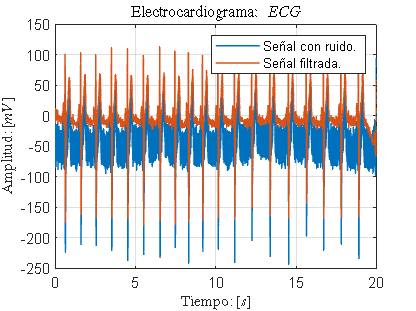

figure 
set(gcf, "color", "w");
plot(t, datar,t,dataf, linewidth = 1);
legend("Señal con ruido.","Señal filtrada.");
grid on;
ylabel("Amplitud: $[mV]$", LineWidth = 3, FontSize = 10, Interpreter="latex");
xlabel("Tiempo: $[s]$",LineWidth = 3, FontSize = 10, Interpreter="latex");
title("Electrocardiograma:  $ECG$",LineWidth = 3,Interpreter="latex");

**Etapa de filtrado**

Filtro notch

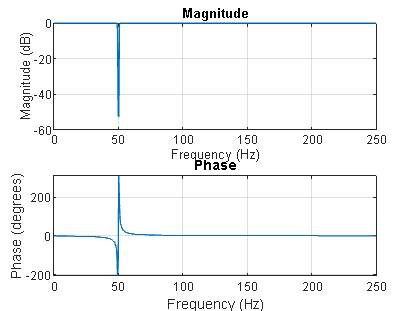

furi2(datar,dataf,Fs);
fc = [49 51]; % frecuencia de rechazo 
wp=fc/(Fs/2);  % banda de rechazo 
[num, den] = ellip(4,0.01,50,wp,"stop");% notch
freqz(num,den,[],Fs); % respueste en frecuencia filtro

datar = filtfilt(num,den,datar); % aplicacion filtro
furi2(datar,dataf,Fs); % graficar espectros 

Filtro pasabanda 

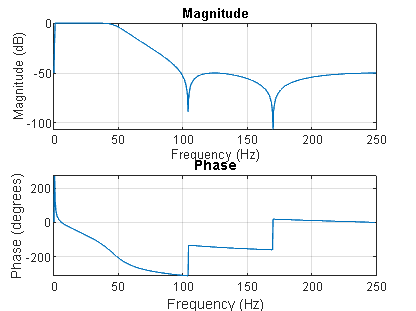

fc = [1 35];
wp=fc/(Fs/2);
[num, den] = ellip(4,0.01,50,wp,"bandpass");
freqz(num,den,[],Fs);

filtrada = filtfilt(num,den,datar);

Alisado, normalizacion y recorte de señal.

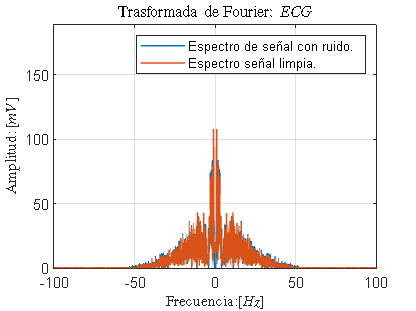

furi2(filtrada,dataf,Fs);

h = ones(1,5);
result=conv(filtrada,h,"same");
result = normalize(result,"zscore");
result = normalize(result,"range", [-10 , 10]);
tr = 1.5; % tiempo a recortar al inicio y final de la señal
nm = round(tr/Ts);
resultado = result(nm:1:end-nm);
if (mean(resultado)>0)
    resultado = -1*resultado;
end
l = length(resultado);
t = (0:l-1)*Ts;

Graficar resultados

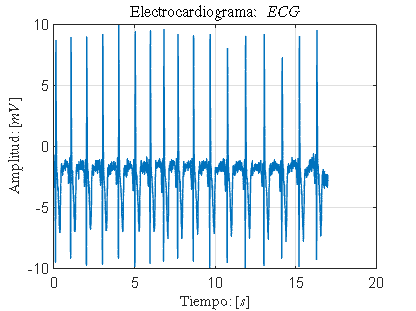

figure 
set(gcf, "color", "w");
plot(t, resultado, linewidth = 1);
%legend("Señal con ruido filtrda.","Señal filtrada original.");
grid on;
ylabel("Amplitud: $[mV]$", LineWidth = 3, FontSize = 10, Interpreter="latex");
xlabel("Tiempo: $[s]$",LineWidth = 3, FontSize = 10, Interpreter="latex");
title("Electrocardiograma:  $ECG$",LineWidth = 3,Interpreter="latex");

## Calcular emvolvente de la señal

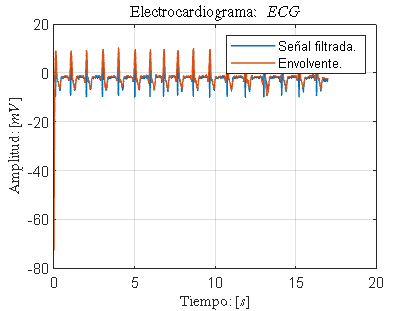

[a1 ,b1] = envelope(resultado,20,"peak"); %
figure
set(gcf, "color", "w");
plot(t,resultado,t,a1, linewidth = 1);
legend("Señal filtrada.","Envolvente.");
grid on;
ylabel("Amplitud: $[mV]$", LineWidth = 3, FontSize = 10, Interpreter="latex");
xlabel("Tiempo: $[s]$",LineWidth = 3, FontSize = 10, Interpreter="latex");
title("Electrocardiograma:  $ECG$",LineWidth = 3,Interpreter="latex");

## Encontrar y ubicar picos

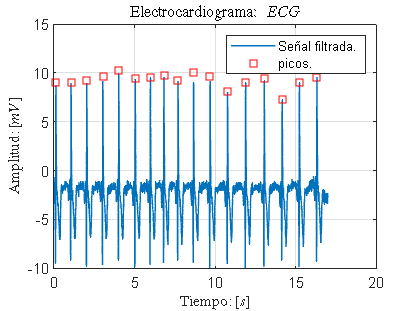


[p1 ,p2] = findpeaks(a1,"MinPeakHeight",3.5);
figure
set(gcf, "color", "w");
plot(t,resultado,t(p2),p1,"sr", linewidth = 1);
legend("Señal filtrada.","picos.");
grid on;
ylabel("Amplitud: $[mV]$", LineWidth = 3, FontSize = 10, Interpreter="latex");
xlabel("Tiempo: $[s]$",LineWidth = 3, FontSize = 10, Interpreter="latex");
title("Electrocardiograma:  $ECG$",LineWidth = 3,Interpreter="latex");

## Ventanado

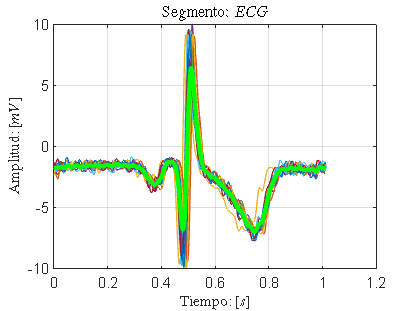

for i = 1 : length(p2)-1
    val(i) =  (p2(i+1)-p2(i));
end
prom = round((mean(val))/2);
t2 = (0 : 2*prom)*Ts;
c = 1;
promedios = 0;
figure
set(gcf, "color", "w");
for i = 2 : length(p2)-1 
    ventana{c} = resultado(p2(i)-prom : p2(i)+prom);
    promedios = ventana{c}+promedios;
    plot(t2,ventana{c});
    hold on
    c = c+1;
end
promedios = promedios/(c-1);
plot(t2,promedios,LineWidth=3,Color="g");
grid on
ylabel("Amplitud: $[mV]$", LineWidth = 3, FontSize = 10, Interpreter="latex");
xlabel("Tiempo: $[s]$",LineWidth = 3, FontSize = 10, Interpreter="latex");
title("Segmento:  $ECG$",LineWidth = 3,Interpreter="latex");

hold off;